# Local Planner Simulation

## function import

addpath("utils/env/", "utils/data/map/", "utils/plot/", "utils/animation/");
addpath("local_planner/");
addpath("global_planner/graph_search/");
addpath("global_planner/sample_search/");

## initialize

clear all;
clc;

% start and goal pose
start = [2, 2, 0];
% goal = [14, 14, pi / 2];
rng(9876, 'twister'); % set seed
goals = randi([10, 14], 3, 2);  % uniform distribution

global_planners = ["a_star", "dijkstra"];
local_planners = ["rpp_plan", "lqr_plan", "mpc_plan"];

## **Simulation loop over various maps, goal poses, global and local planners**

global_costs = {};
dijkstra_local_costs = {};
dijkstra_local_time = {};
a_star_local_costs = {};
a_star_local_time = {};

%% loop over maps
for i = 1:10
    filename = "gridmap_15x15_scene" + i + ".mat";
    load(filename);
    map_size = size(grid_map);

    %% loop over random goal poses
    for i = 1:3
        goal = [goals(i, :), pi / 2];
        grid_map(goal(1), goal(2)) = 1;
        
        %% loop over global planners
        for global_planner_name = global_planners
            global_planner = str2func(global_planner_name);
            [path, global_flag, cost, expand] = global_planner(grid_map, start(:, 1:2), goal(:, 1:2));
            global_costs{end + 1} = [global_planner_name, cost];

            %% loop over local planners
            for local_planner_name = local_planners
                local_planner = str2func(local_planner_name);

                [pose, traj, local_flag, velocity] = local_planner(start, goal, "path", path, "map", grid_map);
                [time_cost, local_distance_cost] = calculate_cost(start, goal, pose, velocity);
                %% TODO save time and distance cose
                if global_planner_name == 'dijkstra'
                    dijkstra_local_time{end + 1} = [local_planner_name, time_cost];
                    dijkstra_local_costs{end + 1} = [local_planner_name, local_distance_cost];
                else
                    a_star_local_time{end + 1} = [local_planner_name, time_cost];
                    a_star_local_costs{end + 1} = [local_planner_name, local_distance_cost];
                end
            end
        end
    end
end

# Visualization with boxplot

#### Local mapping with Dijkstra planner

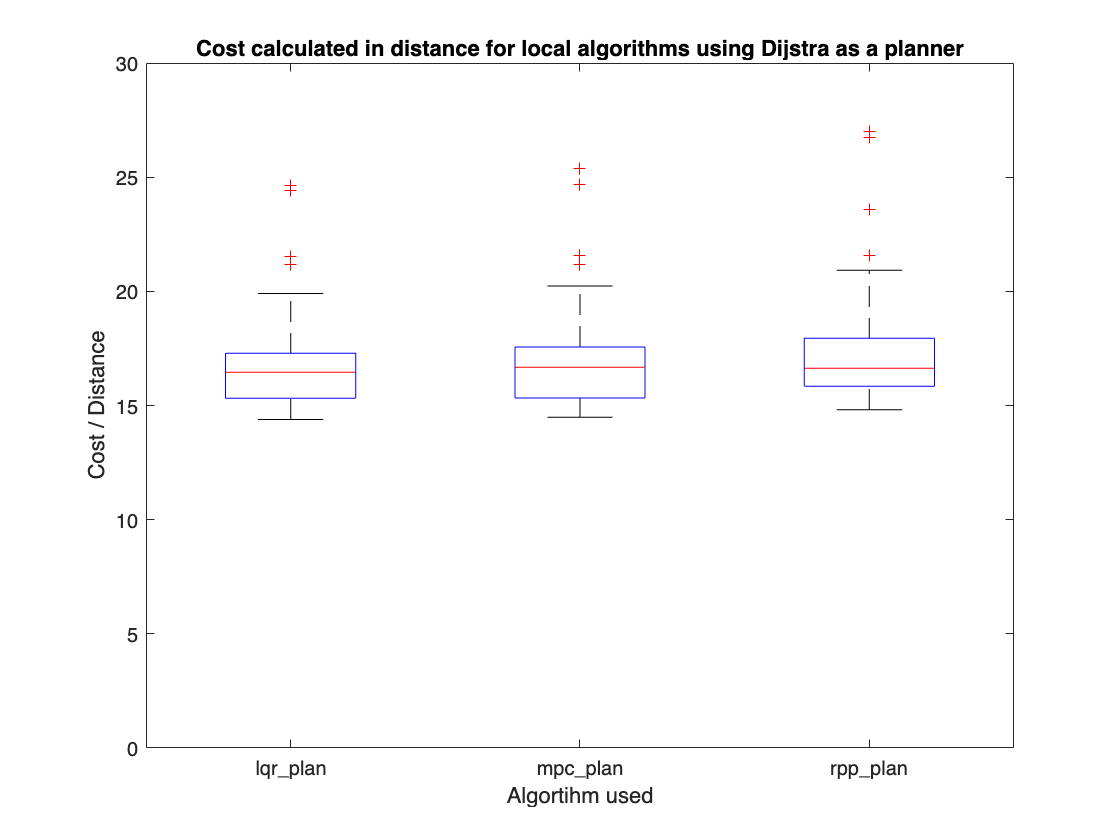

used_algorithm = cellfun(@(x) x{1}, dijkstra_local_costs, 'UniformOutput', false);
found_costs = cellfun(@(x) str2double(x{2}), dijkstra_local_costs);
[unique_algorithms, ~, group_idx] = unique(used_algorithm);
boxplot(found_costs, group_idx, 'Labels', unique_algorithms);
ylim([0, 30]);
ylabel('Cost / Distance');
xlabel('Algortihm used');
title('Cost calculated in distance for local algorithms using Dijstra as a planner');

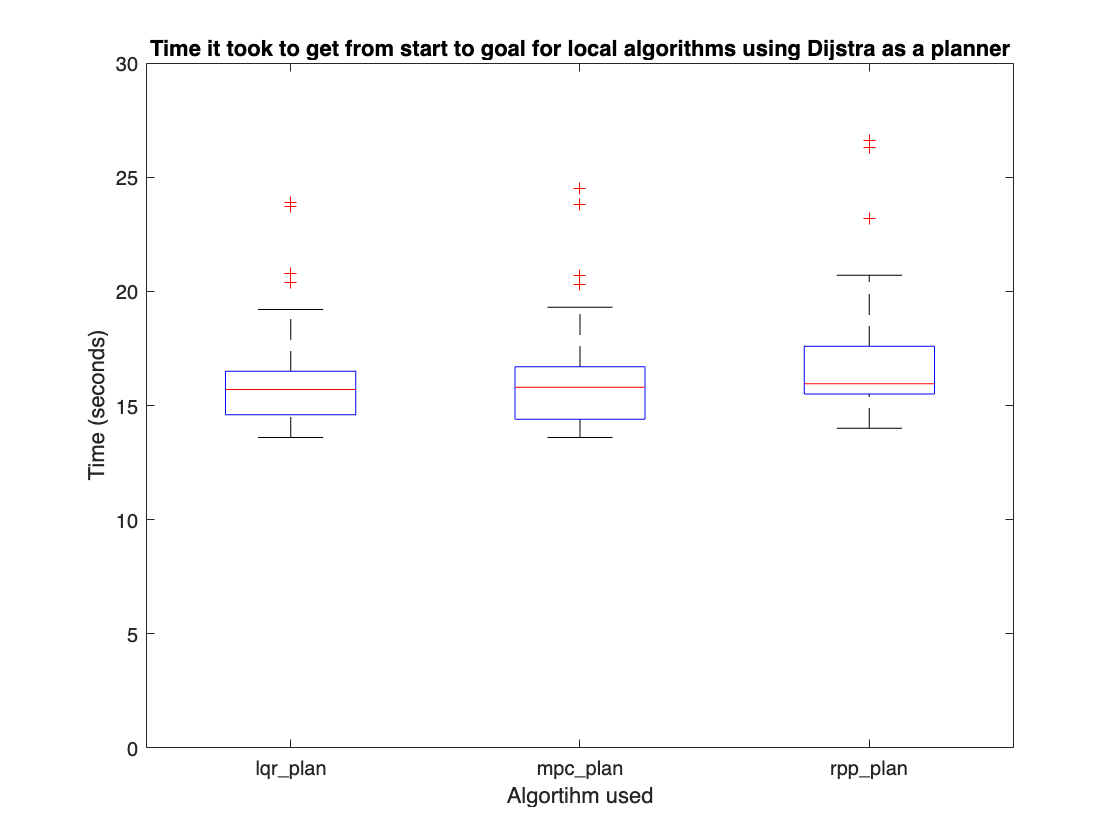

used_algorithm = cellfun(@(x) x{1}, dijkstra_local_time, 'UniformOutput', false);
found_time = cellfun(@(x) str2double(x{2}), dijkstra_local_time);
[unique_algorithms, ~, group_idx] = unique(used_algorithm);
boxplot(found_time, group_idx, 'Labels', unique_algorithms);
ylim([0, 30]);
ylabel('Time (seconds)');
xlabel('Algortihm used');
title('Time it took to get from start to goal for local algorithms using Dijstra as a planner');

#### Local mapping with A* planner

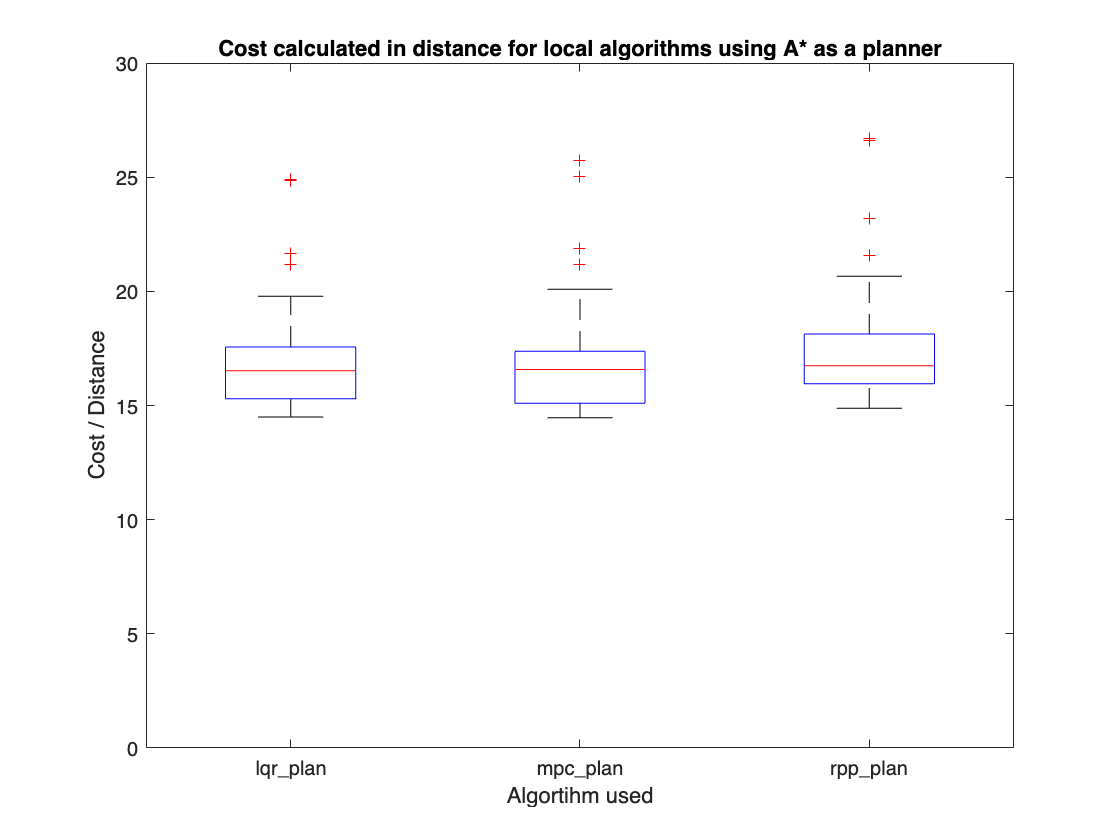

used_algorithm = cellfun(@(x) x{1}, a_star_local_costs, 'UniformOutput', false);
found_costs = cellfun(@(x) str2double(x{2}), a_star_local_costs);
[unique_algorithms, ~, group_idx] = unique(used_algorithm);
boxplot(found_costs, group_idx, 'Labels', unique_algorithms);
ylim([0, 30]);
ylabel('Cost / Distance');
xlabel('Algortihm used');
title('Cost calculated in distance for local algorithms using A* as a planner');

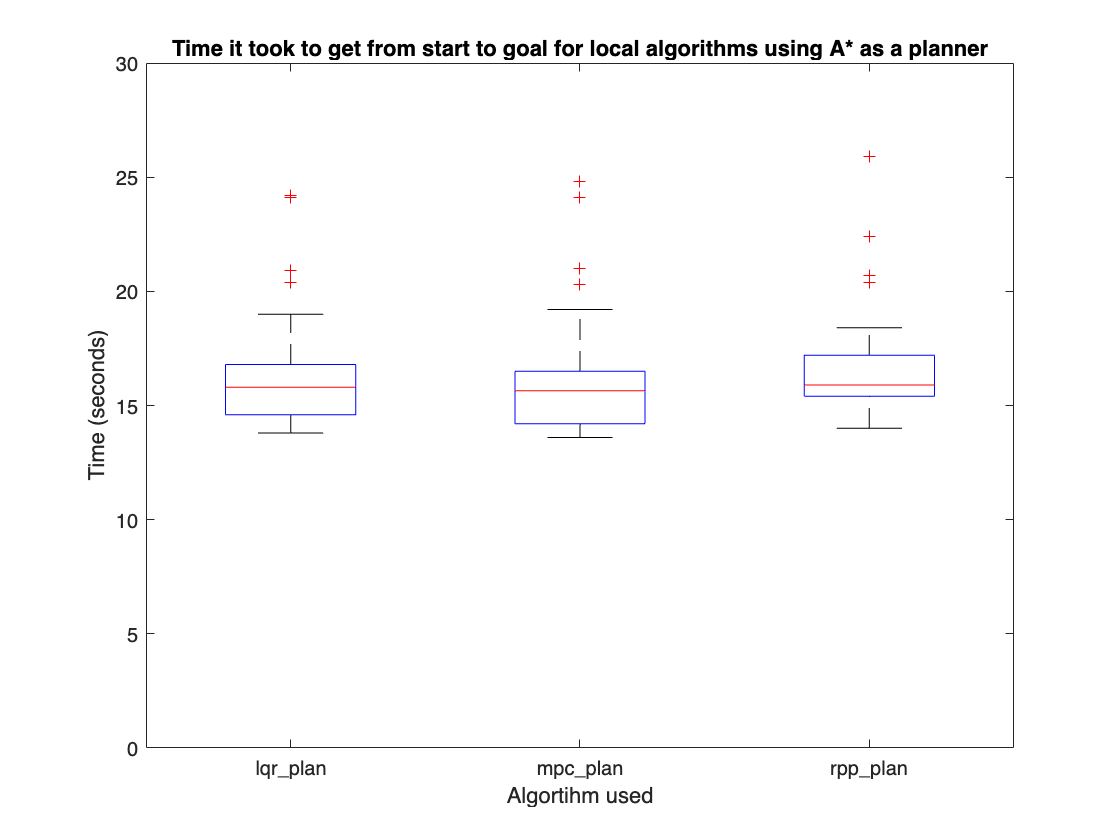

used_algorithm = cellfun(@(x) x{1}, a_star_local_time, 'UniformOutput', false);
found_time = cellfun(@(x) str2double(x{2}), a_star_local_time);
[unique_algorithms, ~, group_idx] = unique(used_algorithm);
boxplot(found_time, group_idx, 'Labels', unique_algorithms);
ylim([0, 30]);
ylabel('Time (seconds)');
xlabel('Algortihm used');
title('Time it took to get from start to goal for local algorithms using A* as a planner');